clc
clear
close all

fs = 41.667e3;

% Steering of main lobe
steerAng =127.01

steerAng = 90.0100

xs = cosd(steerAng);

c = 343

c = 343


micArray = [0.0    0.3333    0.4286    0.5000    0.5714    0.6667    1.0];
spacingsULA1 = [micArray(1) micArray(4) micArray(7)];
spacingsULA2 = [micArray(2)-micArray(2) micArray(4)-micArray(2) micArray(6)-micArray(2)];
spacingsULA3 = [micArray(3)-micArray(3) micArray(4)-micArray(3) micArray(5)-micArray(3)];

tauULA1 = -(spacingsULA1*xs)/c;
tauULA2 = -(spacingsULA2*xs)/c;
tauULA3 = -(spacingsULA3*xs)/c;
offsetULA1 = round(tauULA1*fs);
offsetULA2 = round(tauULA2*fs);
offsetULA3 = round(tauULA3*fs);

cfULA1 = 1700;
cfULA2 = [cfULA1 4500];
cfULA3 = cfULA2(2);
FIRULA1 = makeFIR(cfULA1, 60, fs, 'low');
FIRULA2 = makeFIR(cfULA2, 60, fs, 'bandpass');
FIRULA3 = makeFIR(cfULA3, 60, fs, 'high');

fmax = 20.8e3;
%freqList = linspace(0, fmax, 209) % 0 til fmax med 100 Hz hop
freqList = linspace(0, fmax-300, 42) % 0 til 20.5 kHz med 500 Hz hop

freqList =            0         500        1000        1500        2000        2500        3000        3500        4000        4500        5000        5500        6000        6500        7000        7500        8000        8500        9000        9500       10000       10500       11000       11500       12000       12500       13000       13500       14000       14500       15000       15500       16000       16500       17000       17500       18000       18500       19000       19500       20000       20500


freqList(1) = 50;

degList = (1:5:180) - 1

degList =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100   105   110   115   120   125   130   135   140   145   150   155   160   165   170   175


numTries = 3;

micList = 0:6

micList =      0     1     2     3     4     5     6


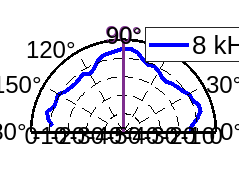


load("freqAdjustment.mat")
for d = 1:length(degList)
    for f = 1:length(freqList)
        for t = 1:numTries
            fileID = fopen('degree_' + string(degList(d)) ...
                + '_freq_' + string(freqList(f)) + '_num_' + string(t-1));
            data = fread(fileID,'single');  
            data = data/(power(2,31)-1);
            numMics = 8;
            numSamples = 190;
            onePacketLength = numSamples*numMics;
            numPacketsInData = floor(length(data)/onePacketLength);
            micData = zeros(length(micList),numSamples*numPacketsInData);
            if exist('sumULA3','var') == 0
                sumULA3 = zeros(length(degList),length(freqList),length(micData)-399);
            end
            for m = 1:7
                for i = 0:numPacketsInData-1
                  
                   micData(m,1+i*numSamples:i*numSamples+numSamples) =  micData(m,1+i*numSamples:i*numSamples+numSamples)' +...
                        data(1+(micList(m)*numSamples)+i*onePacketLength: ... 
                        (micList(m)*numSamples)+i*onePacketLength+numSamples*freqAdjustment(m,f);
                end
            end
            micData = micData * 1/numTries;
            sumULA3(d,f,:) = (micData(3,200+offsetULA3(1):end-200+offsetULA3(1))  + ...
                micData(4,200+offsetULA3(2):end-200+offsetULA3(2)) + ...
                micData(5,200+offsetULA3(3):end-200+offsetULA3(3)))*1/3;

        % offset micData
        % filter
        end
    end
end

outputPowerDB = pow2db(mean(sumULA3.^2,3));
%outputPowerDB = mean(sumULA3.^2,3);
outputPowerDB = outputPowerDB - max(max(outputPowerDB));
        
indexHz = find(freqList==8000); 
circPlot(freqList(indexHz), degList.*pi/180, outputPowerDB(:,indexHz)', steerAng)

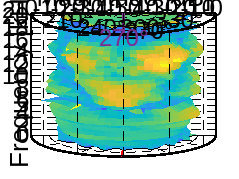

cylindricalPlot(freqList, degList.*pi/180, outputPowerDB', 180-steerAng, [180, 10])

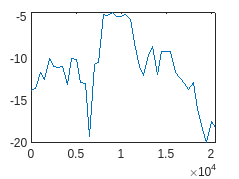


indexDeg = find(degList==90); 
plot(freqList,outputPowerDB(indexDeg,:))

## Get inverse frequency reponse of mic + speaker

mic3Power = zeros(length(micList),length(freqList));
numTries = 3;
for f = 1:length(freqList)
    for t = 1:numTries
        fileID = fopen('degree_' + string(90) ...
            + '_freq_' + string(freqList(f)) + '_num_' + string(t-1));
        data = fread(fileID,'single');  
            data = data/(power(2,31)-1);
            numMics = 8;
            numSamples = 190;
            onePacketLength = numSamples*numMics;
            numPacketsInData = floor(length(data)/onePacketLength);
            for m = 1:7
                for i = 0:numPacketsInData-1
                   mic3Power(m,f) = mic3Power(m,f) + mean(data(1+(micList(m)*numSamples)+i*onePacketLength: ... 
                           (micList(m)*numSamples)+i*onePacketLength+numSamples).^2);
                end
            end
            mic3Power(m,f) = mic3Power(m,f)/numTries;
    end
end
freqAdjustment = sqrt(max(mic3Power')'./mic3Power)

freqAdjustment =    15.5131    4.1314    2.7932    2.4074    2.1663    1.8314    2.1153    2.0801    2.2882    2.4174    3.0136    3.1760    2.9931    4.8804    3.3783    2.5361    1.4995    1.3172    1.0852    1.1558    1.0000    1.0283    1.0345    1.4721    2.0550    2.5599    2.2374    1.7211    1.7457    1.6487    2.2113    2.3532    2.4196    3.2117    2.7830    3.0926    2.5910    3.9629    5.0731   10.4956   15.0242   17.8778
    6.2497    4.2465    2.9651    2.6886    1.9161    2.3622    2.5703    2.5812    3.0505    2.2168    2.2092    2.4972    2.6202    5.5985    3.3444    2.7585    1.6439    1.4752    1.1089    1.0000    1.0334    1.2122    1.3520    1.5836    1.7389    2.4627    2.4743    2.2352    1.8993    2.4947    3.0441    2.0681    1.8290    1.7793    2.5082    3.2575    3.6496    5.0409    7.6611    6.0626    7.0770    6.1941
    3.2417    2.8606    2.2348    2.4505    1.8510    2.0726    2.1068    2.0885    2.5471    1.8571    1.8832    2.5855    2.6230    5.2079 

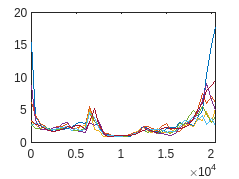

plot(freqList,freqAdjustment)

save("freqAdjustment.mat", 'freqAdjustment')

function coeffs_adjusted = makeFIR(Fc, order, fs, type)
if ~exist('type', 'var') 
    coeffs = fir1(order,2*Fc/fs);
else 
    coeffs = fir1(order,2*Fc/fs, type);
end 
[mag, freq] = freqz(coeffs,1,1024,fs);
magdB = 20*log10(abs(mag));
if length(Fc) == 1
    [~, minIndex] = min(abs(magdB + 3));
    Fc_3dB = freq(minIndex);
    Fc_adjusted = Fc * (Fc/Fc_3dB);
    coeffs_adjusted = fir1(order, 2*Fc_adjusted/fs, type);
elseif length(Fc) == 2
    %[~, minIndexLow] = min(abs(magdB + 3));
    minIndexLow = find(abs(magdB)<3,1);
    minIndexHigh = find(abs(magdB(minIndexLow:end))>3,1) + minIndexLow;
    FcLow_3dB = freq(minIndexLow);
    FcHigh_3dB = freq(minIndexHigh);
    FcLow_adjusted = Fc(1) * (Fc(1)/FcLow_3dB);
    FcHigh_adjusted = Fc(2) * (Fc(2)/FcHigh_3dB);
    coeffs_adjusted = fir1(order, 2*[FcLow_adjusted FcHigh_adjusted]/fs, type);
else
    disp("nederen")
end
end